clc;clear;
m0=input("未增长前网络节点个数m0:");
m=input("引入新节点时新生成的边数m:");
N=input("增长后网络节点总数N:")

N = 500


disp("m0节点连接情况:1表示都是孤立点;2表示构成完全图;3表示随机连接");

m0节点连接情况:1表示都是孤立点;2表示构成完全图;3表示随机连接


se=input("选择初始网络情况:");
if m>m0
    disp("参数不合法");return;
end
x=100*rand(1,m0); %构造初始画图m0个节点
y=100*rand(1,m0);
if se==1
    A=zeros(m0);
elseif se==2
    A=ones(m0);
    A(1:m0+1:m0^2)=0; %对角线元素置0
    %A(eye(size(A)))=0;
else
    A=zeros(m0);
    B=rand(m0);
    B=tril(B); %截取下三角元素
    A(B<=0.1)=1; %概率0.1进行连边
    A=A+A'; %构造邻接矩阵
end
for k=m0+1:N
    x(k)=100*rand; %生成画图坐标
    y(k)=100*rand;
    p=(sum(A)+1)/sum(sum(A)+1); %计算节点连接概率
    pp=cumsum(p); %求累计分布
    A(k,k)=0; %邻接矩阵扩充维数
    ind=[]; %初始集合
    while length(ind)<m
        jj=find(pp>rand); %赌轮法选择连边节点编号
        jj=jj(1);
        ind=union(ind,jj) %使用unicn保证节点不重复
    end
    A(k,ind)=1;
    A(ind,k)=1;%新的邻接矩阵
end

ind = 2

ind = 1

ind = 7

ind = 4

ind = 6

ind = 8

ind = 6

ind = 1

ind = 6

ind = 2

ind = 8

ind = 11

ind = 8

ind = 15

ind = 2

ind = 12

ind = 12

ind = 20

ind = 6

ind = 15

ind = 25

ind = 11

ind = 27

ind = 15

ind = 6

ind = 6

ind = 25

ind = 24

ind = 25

ind = 15

ind = 15

ind = 28

ind = 25

ind = 36

ind = 5

ind = 11

ind = 25

ind = 22

ind = 38

ind = 12

ind = 26

ind = 25

ind = 3

ind = 1

ind = 46

ind = 11

ind = 19

ind = 24

ind = 48

ind = 15

ind = 24

ind = 55

ind = 56

ind = 1

ind = 11

ind = 5

ind = 25

ind = 20

ind = 6

ind = 25

ind = 9

ind = 48

ind = 5

ind = 30

ind = 63

ind = 24

ind = 24

ind = 6

ind = 17

ind = 29

ind = 48

ind = 11

ind = 2

ind = 15

ind = 7

ind = 20

ind = 56

ind = 5

ind = 65

ind = 3

ind = 70

ind = 27

ind = 3

ind = 76

ind = 72

ind = 12

ind = 2

ind = 66

ind = 39

ind = 6

ind = 10

ind = 65

ind = 85

ind = 5

ind = 54

ind = 10

ind = 8

ind = 5

ind = 66

ind = 46

ind = 2

ind = 82

ind = 6

ind = 2

ind = 68

ind = 15

ind = 53

ind = 110

ind = 55

ind = 66

ind = 26

ind = 115

ind = 25

ind = 78

ind = 27

ind = 25

ind = 25

ind = 6

ind = 55

ind = 35

ind = 24

ind = 8

ind = 7

ind = 72

ind = 119

ind = 37

ind = 95

ind = 115

ind = 56

ind = 38

ind = 132

ind = 136

ind = 7

ind = 33

ind = 20

ind = 32

ind = 25

ind = 48

ind = 25

ind = 117

ind = 137

ind = 142

ind = 13

ind = 119

ind = 76

ind = 126

ind = 17

ind = 7

ind = 109

ind = 25

ind = 11

ind = 125

ind = 5

ind = 157

ind = 25

ind = 62

ind = 19

ind = 15

ind = 157

ind = 79

ind = 76

ind = 66

ind = 55

ind = 65

ind = 152

ind = 156

ind = 73

ind = 12

ind = 6

ind = 76

ind = 21

ind = 91

ind = 170

ind = 56

ind = 56

ind = 33

ind = 15

ind = 150

ind = 169

ind = 77

ind = 149

ind = 25

ind = 65

ind = 10

ind = 131

ind = 38

ind = 26

ind = 16

ind = 150

ind = 92

ind = 139

ind = 94

ind = 141

ind = 119

ind = 97

ind = 24

ind = 22

ind = 5

ind = 197

ind = 39

ind = 22

ind = 36

ind = 182

ind = 196

ind = 68

ind = 135

ind = 101

ind = 126

ind = 119

ind = 6

ind = 71

ind = 2

ind = 163

ind = 133

ind = 39

ind = 126

ind = 149

ind = 150

ind = 130

ind = 172

ind = 113

ind = 200

ind = 137

ind = 2

ind = 17

ind = 115

ind = 25

ind = 7

ind = 215

ind = 63

ind = 157

ind = 88

ind = 36

ind = 224

ind = 11

ind = 152

ind = 56

ind = 208

ind = 89

ind = 16

ind = 15

ind = 6

ind = 205

ind = 184

ind = 15

ind = 27

ind = 244

ind = 72

ind = 131

ind = 155

ind = 132

ind = 159

ind = 15

ind = 139

ind = 22

ind = 148

ind = 6

ind = 71

ind = 26

ind = 189

ind = 157

ind = 8

ind = 72

ind = 170

ind = 5

ind = 33

ind = 48

ind = 85

ind = 10

ind = 25

ind = 5

ind = 215

ind = 26

ind = 55

ind = 88

ind = 7

ind = 179

ind = 144

ind = 16

ind = 115

ind = 210

ind = 88

ind = 33

ind = 46

ind = 265

ind = 169

ind = 57

ind = 72

ind = 29

ind = 3

ind = 6

ind = 141

ind = 126

ind = 20

ind = 119

ind = 300

ind = 155

ind = 211

ind = 139

ind = 245

ind = 56

ind = 94

ind = 2

ind = 109

ind = 20

ind = 103

ind = 126

ind = 82

ind = 280

ind = 135

ind = 219

ind = 73

ind = 20

ind = 6

ind = 103

ind = 152

ind = 215

ind = 7

ind = 131

ind = 78

ind = 181

ind = 169

ind = 150

ind = 7

ind = 119

ind = 25

ind = 20

ind = 137

ind = 24

ind = 11

ind = 19

ind = 127

ind = 324

ind = 75

ind = 91

ind = 15

ind = 249

ind = 182

ind = 13

ind = 157

ind = 48

ind = 333

ind = 298

ind = 48

ind = 270

ind = 276

ind = 217

ind = 344

ind = 73

ind = 72

ind = 313

ind = 26

ind = 172

ind = 5

ind = 251

ind = 256

ind = 20

ind = 16

ind = 224

ind = 152

ind = 77

ind = 195

ind = 93

ind = 9

ind = 121

ind = 26

ind = 68

ind = 24

ind = 224

ind = 276

ind = 70

ind = 94

ind = 327

ind = 130

ind = 24

ind = 358

ind = 201

ind = 254

ind = 141

ind = 70

ind = 313

ind = 7

ind = 177

ind = 7

ind = 74

ind = 54

ind = 271

ind = 9

ind = 60

ind = 92

ind = 227

ind = 207

ind = 274

ind = 281

ind = 25

ind = 158

ind = 130

ind = 33

ind = 25

ind = 134

ind = 324

ind = 103

ind = 6

ind = 208

ind = 139

ind = 5

ind = 299

ind = 118

ind = 95

ind = 179

ind = 221

ind = 119

ind = 260

ind = 230

ind = 259

ind = 126

ind = 126

ind = 224

ind = 6

ind = 106

ind = 126

ind = 34

ind = 1

ind = 318

ind = 398

ind = 388

ind = 259

ind = 47

ind = 5

ind = 6

ind = 11

ind = 337

ind = 26

ind = 230

ind = 120

ind = 240

ind = 65

ind = 77

ind = 215

ind = 218

ind = 197

ind = 365

ind = 407

ind = 108

ind = 411

ind = 228

ind = 422

ind = 117

ind = 372

ind = 223

ind = 389

ind = 129

ind = 219

ind = 455

ind = 29

ind = 189

ind = 7

ind = 36

ind = 218

ind = 33

ind = 410

ind = 365

ind = 12

ind = 213

ind = 332

ind = 11

ind = 89

ind = 184

ind = 393

ind = 425

ind = 273

ind = 337

ind = 72

ind = 38

ind = 364

ind = 423

ind = 408

ind = 407

ind = 94

ind = 244

ind = 75

ind = 83

ind = 176

ind = 31

ind = 179

ind = 131

ind = 249

ind = 190

ind = 53

ind = 433

ind = 241

ind = 5

ind = 208

ind = 129

ind = 131

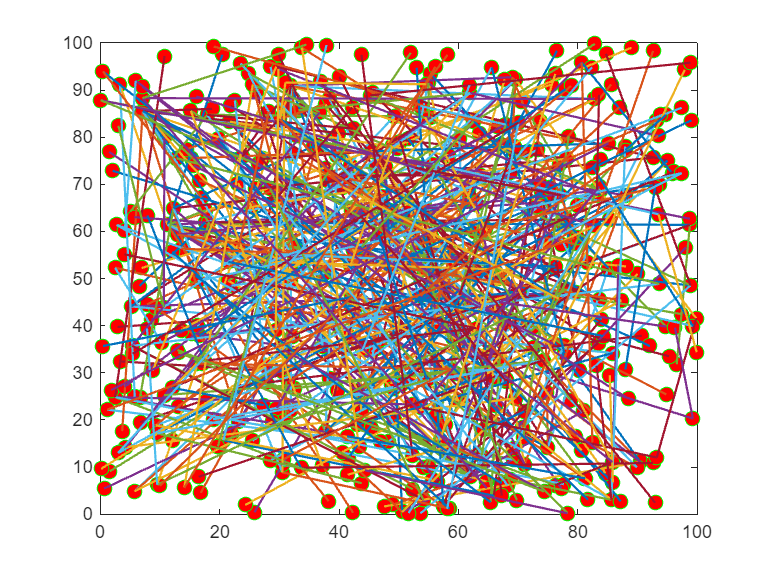

plot(x,y,'ro','MarkerEdgeColor','g','MarkerFaceColor','r','MarkerSize',8)
hold on;
A=tril(A);
[i,j]=find(A); %找邻接矩阵下三角元素的非零元素
for k=1:length(i)
    plot([x(i(k)),x(j(k))],[y(i(k)),y(j(k))],'LineWidth',1.2)
    %filename=sprintf('plot_%d.png',k);
    %saveas(gcf,filename);
end

deg=sum(A) %计算各节点的度

deg =      5    10     4     1    14    20    12     6     3     4    11     6     2     0    14     4     3     0     3     9     1     4     0    10    21     8     4     1     3     1     1     1     6     1     1     4     1     4     3     0     0     0     0     0     0     3     1     7     0     0


ave_degree=sum(deg)/N %计算平均度

ave_degree = 0.9900

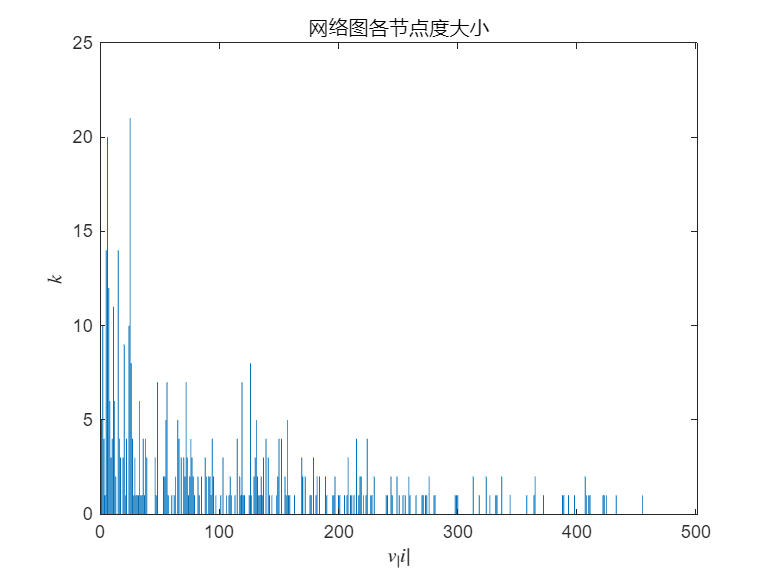

figure,bar([1:N],deg); %画各节点度柱状图
title('网络图各节点度大小');
xlabel('$v_|i|$','Interpreter','latex');
ylabel('$k$','Interpreter','latex');

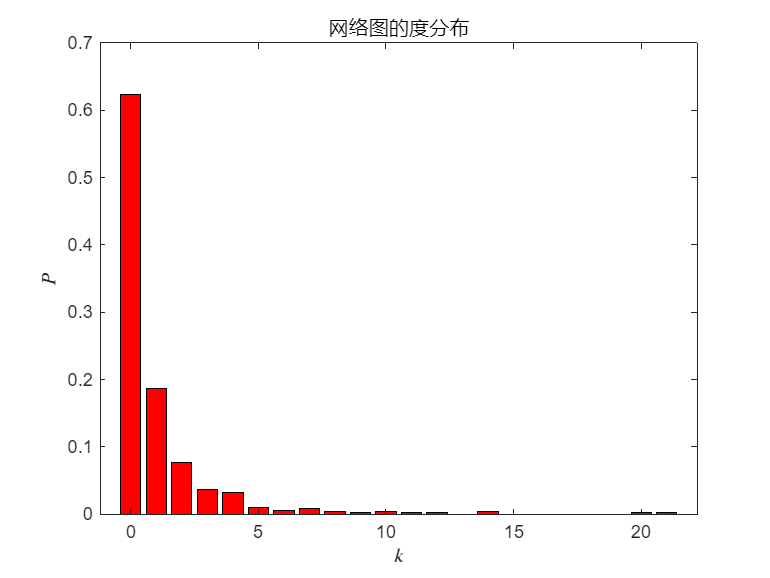

degrange=minmax(deg); %求度的取值范围
pinshu=hist(deg,[degrange(1):degrange(2)]); %求度取值的频数
df=pinshu/N; %度的频率分布
figure,bar([degrange(1):degrange(2)],df,'r'); %画度分布柱状图
title('网络图的度分布');
xlabel('$k$','Interpreter','latex');
ylabel('$P$','Interpreter','latex');

Matlab_to_Pajek(A,2)

str = 'Pajek_data2.net'